# **WORD算法(阵列方向图控制理论与算法研究)**

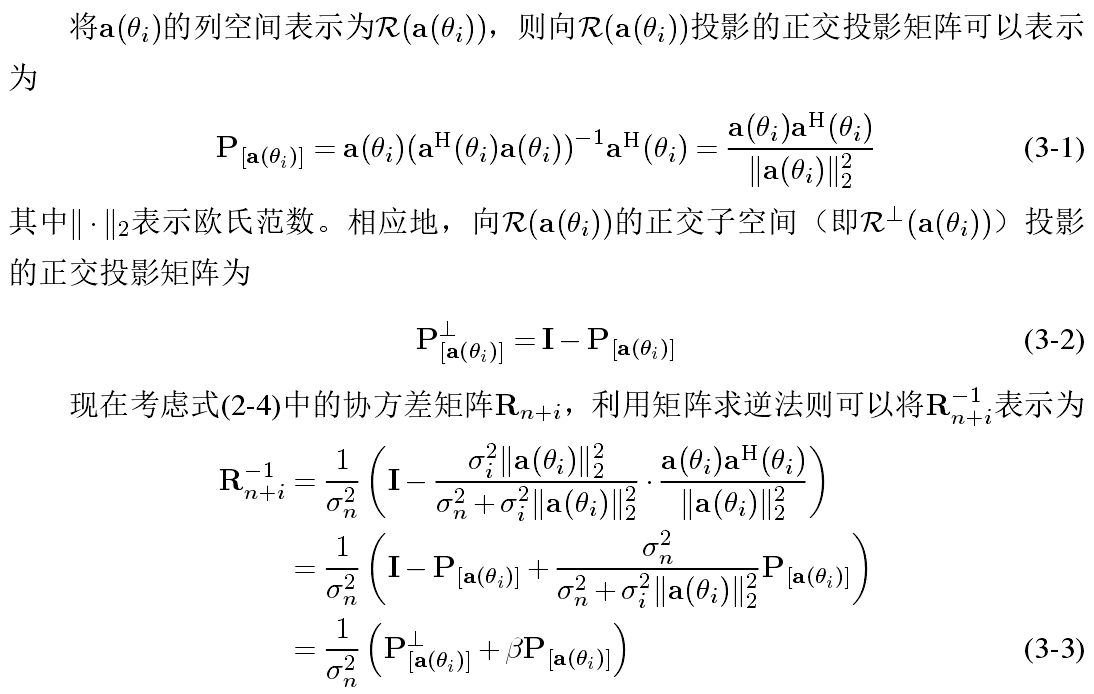

这里有个问题，如果beta = 1

那么P+P_v = I

R_i^-1 = 为单位阵？啥都没干  所以beta=1方向图不变？  beta = 1 干扰功率为0

**补充说明**

**根据MSINR准则,DBF为a(theta0),干扰的协方差矩阵为R_je^-1**

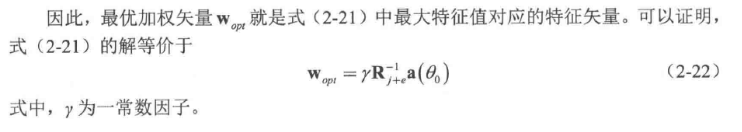

通过word算法构造逆矩阵，即为 $a(\theta_i)$投影矩阵$P$ + $a(\theta_i)$的正交投影矩阵 即为式(3-3)

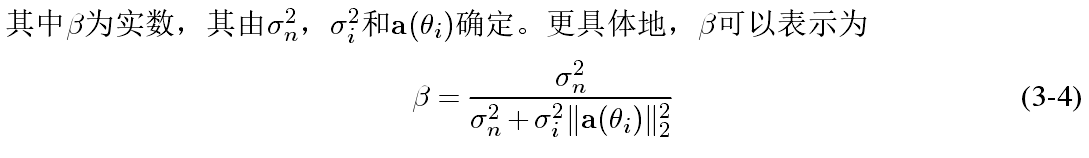

因此 最优权矢量可以表示为

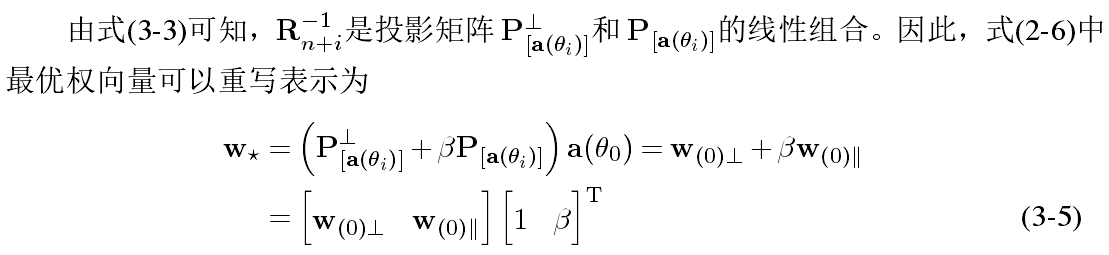

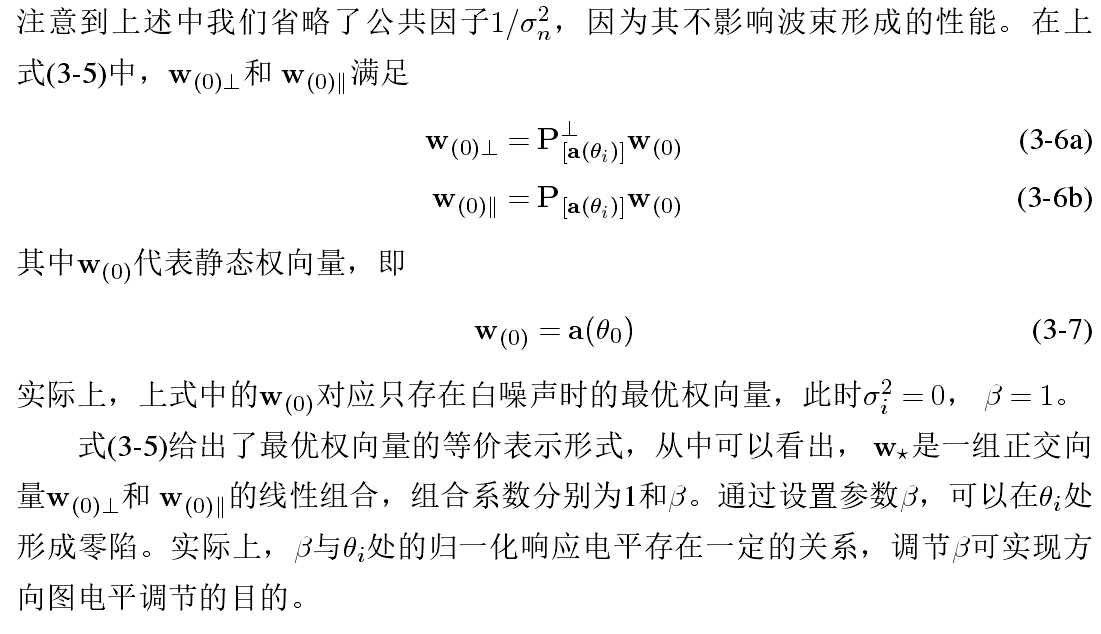

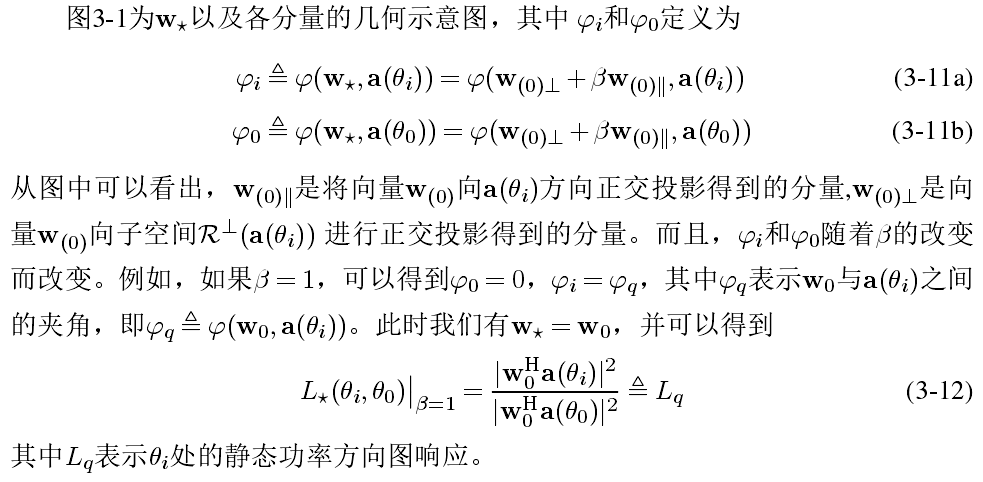

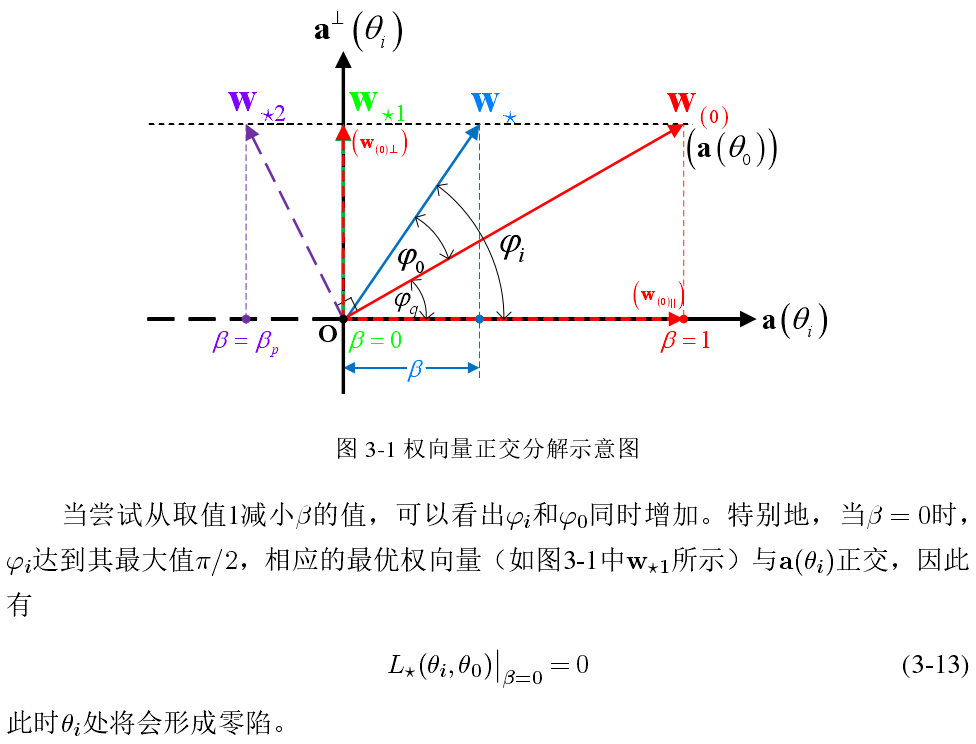

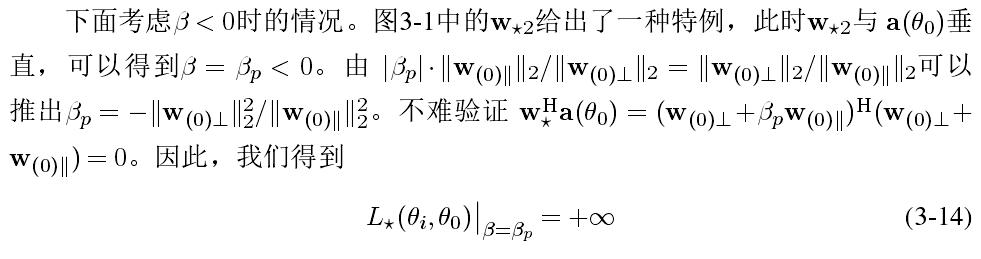

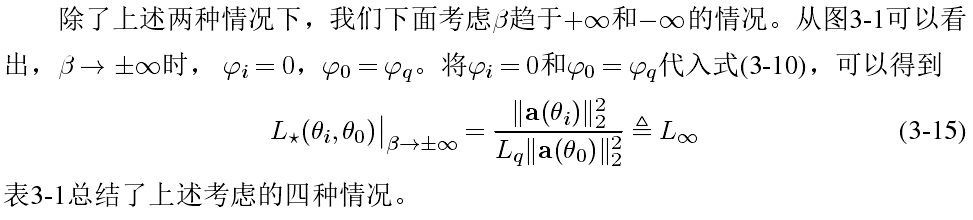

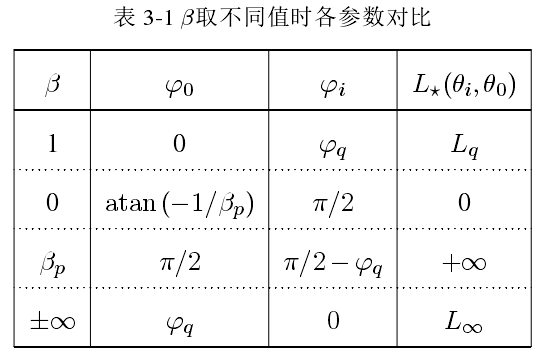

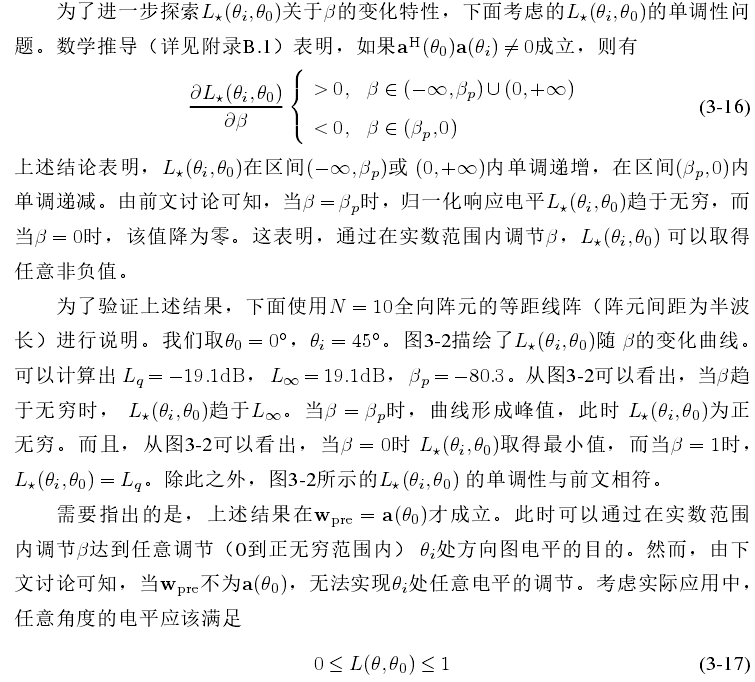

%--------------------------------------------------------------------------
%   初始化
%--------------------------------------------------------------------------
clear;clc;

%--------------------------------------------------------------------------
%   参数设置
%--------------------------------------------------------------------------
N = 64;                                                                     %阵元个数

%--------------------------------------------------------------------------
%   生成参数
%--------------------------------------------------------------------------
lambda = 1;                                                                 %波长
dd = lambda/2;                                                              %阵元间距d = lambda/2
d = 0:dd:(N-1)*dd;                                                          %构建阵列坐标
angle_axis = -90:0.01:90;

theta_tgt = -45;
theta_jam = [10 30];
w_output = word( N, theta_tgt, @hann ,lambda, d, theta_jam,0);

[~,~,L_dB] = L_norm_array_pattern(w_output,angle_axis);
%--------------------------------------------------------------------------
%   可视化
%--------------------------------------------------------------------------
plot(angle_axis,L_dB,'LineWidth',1.5);grid on;hold on
for idx = 1:length(theta_jam)
    plot([theta_jam(idx) theta_jam(idx)],[-200 0],'--','LineWidth',1.5)
end
axis([-90 90 -120 0]);hold off
title(['目标指向-> ' num2str(theta_tgt) ' 干扰指向-> ' num2str(theta_jam)])